close all; clc

syms x1 x2
syms epsilon positive
f1 = x2;
f2 = epsilon*x2*(1-x1^2-x2^2) - x1;

% equilibrium points
sln = solve([f1 f2], [x1 x2]);
sln.x1

$$ans = 0$$

sln.x2

$$ans = 0$$


% type of equilibrium point
J = jacobian([f1 f2], [x1 x2]);
J = subs(J, [x1 x2], [0 0])

$$J = \left(\begin{array}{cc} 0 & 1\\ -1 & \epsilon \end{array}\right)$$

eig(J)

$$ans = \left(\begin{array}{c} \frac{\epsilon }{2}-\frac{\sqrt{\left(\epsilon -2\right)\,\left(\epsilon +2\right)}}{2}\\ \frac{\epsilon }{2}+\frac{\sqrt{\left(\epsilon -2\right)\,\left(\epsilon +2\right)}}{2} \end{array}\right)$$

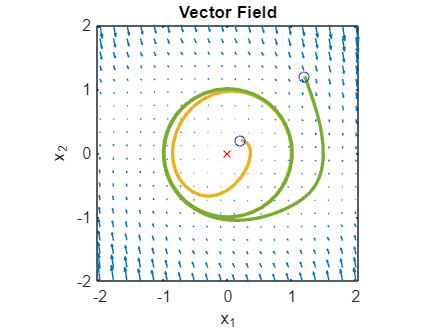

% Create vector field
close all;
x = linspace(-2,2,20);
y = linspace(-2,2,20);
[X,Y] = meshgrid(x,y);

epsilon = 1;

DX = Y;                 
DY = epsilon*Y.*(1-X.^2-Y.^2) - X;

% make arrows the same length
quiver(X,Y,DX,DY,1);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")

hold on;
plot(0, 0, 'rx')

f= @(t,P) [P(2); epsilon*P(2).*(1-P(1).^2-P(2).^2)-P(1)];
a = [0.2 1.2];
b = [0.2 1.2];
for i = 1:numel(a)
    [t,s] = ode45(f,[0 30], [a(i) b(i)]);
    plot(s(:,1),s(:,2),'LineWidth',2)
    plot(a(i), b(i), 'bo')
end
hold off